**Import Data**

%Clear workspace
clear all
clc

%Import F file
File = uigetfile('*.xlsx');
F = xlsread(File);

%Import Fneu file
File2 = uigetfile('*.xlsx');
Fneu = xlsread(File2);

%Import file with info if it is a cell or not
File3 = uigetfile('*.xlsx');
IsCell = xlsread(File3);
cells = IsCell==1;

%Keep only info about cells in both matrixes
F = F(cells, :);
Fneu = Fneu(cells, :);

**Calculate DF/F0**

df = (F-Fneu)./Fneu;

**Plot to confirm**

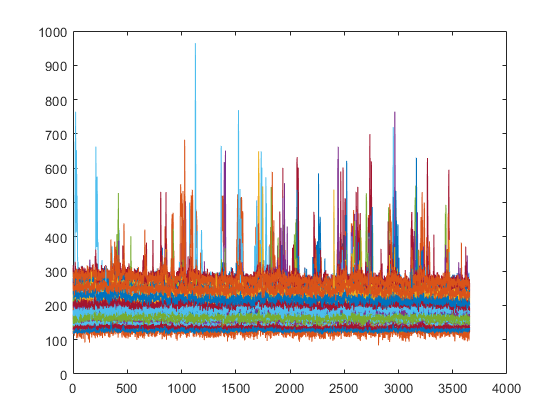

plot((1:3656), F)

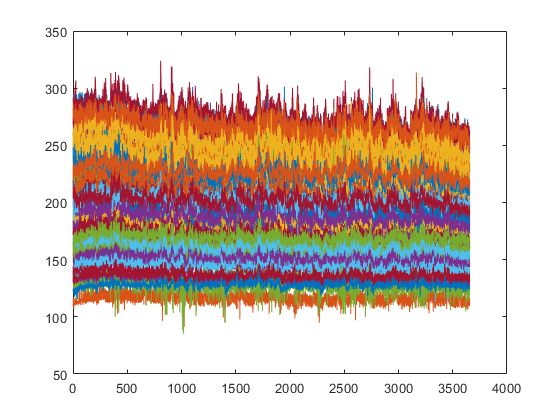

plot((1:3656), Fneu)

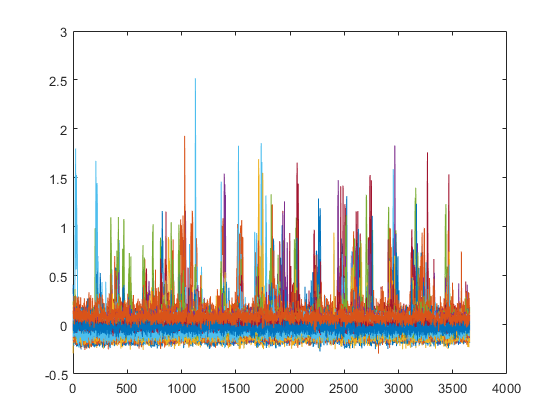

plot((1:3656), df)

**Save result (Delta F/F0) to Excel**

xlswrite('DF_F0.xlsx', df);